# OR06 Sensitivity Analysis

Consider the previous example


$$\max \;80x+120x\;s\ldotp t\ldotp \left\lbrack \begin{array}{cc}
1 & 2\\
8 & 7\\
7 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
6\\
28\\
4
\end{array}\right\rbrack \textrm{and}\;x,y\ge 0$$


We can plot the feasible region using the following code

% define and plot objective function
wx = 80;
wy = 120;

% define and plot objective function and normalized gradient
close all;
f = @(x,y) wx*x + wy*y;
[X, Y] = meshgrid(linspace(0,4, 5));
contourf(X, Y, f(X,Y), 30); colorbar;
xlim([0,4]), ylim([0,4]), axis equal, hold on;

% plot (normalized) gradient
grad_f = [wx; wy]; grad_f = grad_f / norm(grad_f);
quiver(2, 3, grad_f(1), grad_f(2), 'linewidth', 2)

% plot boundary of feasible region
t = linspace(0,4, 2);
LW = 'linewidth';
lw=3;
plot(t, (6-t)/2, '-k',LW,lw)                      % constraint bdry 1
plot(t, (28-8*t)/7, '-k',LW,lw)                   % constraint bdry 2
plot(3*ones(size(t)), t, '-k',LW,lw)              % constraint bdry 3
plot(zeros(size(t)), t, '-k',LW,lw)               % constraint bdry 4
plot(t, zeros(size(t)), '-k',LW,lw)               % constraint bdry 5

% compute optimal solution
A = [1 2; 8 7; 1 0];    % constraint matrix
b = [6 28 3];           % constraing rhs
x = linprog(-[wx; wy],A,b,[],[],[0;0],[]);

Optimal solution found.



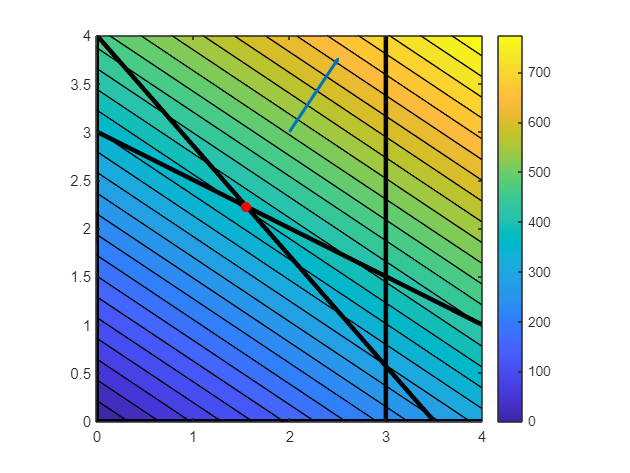

plot(x(1), x(2), 'r.','markersize',20)